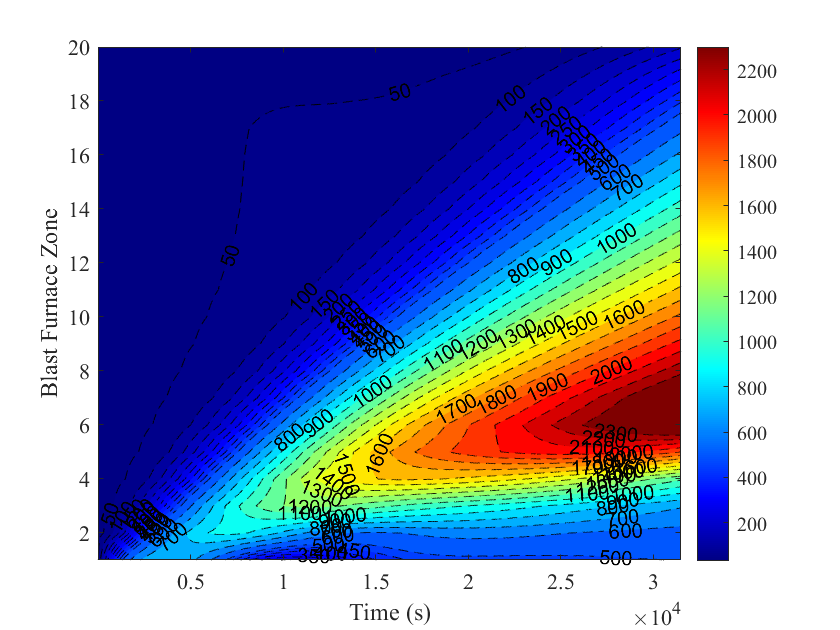

ChemData = readtable('chemdata.csv');
ReactionData = readtable('reactdata.csv');
% int

tspan = 126000; 
CokeOreRatio = 3; 
HearthDiameter = 11.2; 
HearthHeight = 23.9; 
WallThickness = 1.8; 
ThermalConductivity = 30; 
HotBlastRate = 33;
HotBlastTemp = 1100; 
OxygenEnrichment = 3; 
Temp_ext = 40; 
Temp_initial = 40; 
SilicaImpurity = 2; 
nZones = 20;
Res = 4; 

[RateCoef,Rate,Hr,SpeciesVolume] = deal(zeros([tspan/Res height(ReactionData) nZones]));
[nTotal,CpnAv,VolUsed,VolUsedFraction,VolAvailable,VolAvailableFraction,HrNet] = deal(zeros([tspan/Res nZones]));
[dTdt,dhWall,dhProducts,dhBurdenDescentNet,dhGasAscentNet,dhHotBlast,HNet] = deal(zeros([tspan/Res nZones]));
[FeedRate,dnOut] = deal(zeros([tspan/Res 13]));
[dnBurdenDescent,dnGasAscent] = deal(zeros([tspan/Res 13 nZones]));
[VolUsedNew,VolAvailableBurden] = deal(zeros([(tspan/Res) 1]));
n = zeros([(tspan/Res)+1 13 nZones]);
dn = zeros([tspan/Res 13 nZones]);
Temp = zeros([(tspan/Res)+1 nZones]);

SpeciesBurden = [1 5 6 7 8 10 11 12 13]; 
SpeciesGas = [2 3 4 9]; 
SpeciesProducts = [8 13]; 

[RateCoef,Rate,Hr,SpeciesVolume] = deal(zeros([tspan/Res height(ReactionData) nZones]));
[nTotal,CpnAv,VolUsed,VolUsedFraction,VolAvailable,VolAvailableFraction,HrNet] = deal(zeros([tspan/Res nZones]));
[dTdt,dhWall,dhProducts,dhBurdenDescentNet,dhGasAscentNet,dhHotBlast,HNet] = deal(zeros([tspan/Res nZones]));
[FeedRate,dnOut] = deal(zeros([tspan/Res 13]));
[dnBurdenDescent,dnGasAscent] = deal(zeros([tspan/Res 13 nZones]));
[VolUsedNew,VolAvailableBurden] = deal(zeros([(tspan/Res) 1]));
n = zeros([(tspan/Res)+1 13 nZones]);
dn = zeros([tspan/Res 13 nZones]);
Temp = zeros([(tspan/Res)+1 nZones]);

% Define the Stoichiometric Coefficient Matrix:

M = [[-2,-1,2,0,0,0,0,0,0,0,0,0,0,0];... % Reaction 1: 2C + O2 -> 2CO
[0,-1,-2,2,0,0,0,0,0,0,0,0,0,0];...      % Reaction 2: 2CO + O2 -> 2CO2
[0,0,-1,1,-3,2,0,0,0,0,0,0,0,0];...      % Reaction 3: 3Fe2O3 + CO -> 2Fe3O4 + CO2
[0,0,-1,1,0,-1,3,0,0,0,0,0,0,0];...      % Reaction 4: Fe3O4 + CO -> 3FeO + CO2
[0,0,-1,1,0,0,-1,1,0,0,0,0,0,0];...      % Reaction 5: FeO + CO -> Fe + CO2
[0,0,0,1,0,0,0,0,0,-1,1,0,0,0];...       % Reaction 6: CaCO3 -> CaO + CO2
[0,0,0,0,0,0,0,0,0,0,-1,-1,1,0]]';       % Reaction 7: CaO + SiO2 -> CaSiO3

% INITIAL CALCULATIONS

% Calculate Molar Volumes for each species as a new column in ChemData: 计算每个物种的摩尔体积，作为ChemData的一个新列：

ChemData.Mvol = ChemData.Mmass./ChemData.Density;

% 炉膛尺寸计算：

HearthVolume = pi*((0.5*HearthDiameter)^2)*HearthHeight; % 炉膛总容积[m^3]
AreaWall = 2*pi*(0.5*HearthDiameter)*HearthHeight; %  总的内部侧壁面积[m^2] 。
AreaWallZone = AreaWall / nZones; %每个区的内侧壁面积[m^2] 

% 计算热风中氧气的摩尔数[mol/s]：

OxygenInAir = 0.21;
HotBlastRateO2 = (HotBlastRate*Res)/ChemData.Mvol(14)*(OxygenInAir+(OxygenEnrichment/100)); 
HotBlastRateN2 = (HotBlastRate*Res)/ChemData.Mvol(14)*(1-(OxygenInAir+OxygenEnrichment/100));

% 计算标准温度（25℃）下的反应热

StdHr = sum(M.*ChemData.stdHForm);

%计算墙体热损失计算的系数：

kThermalWall = ThermalConductivity / WallThickness;

% 计算炉料浓度的体积系数：

A(1) = ChemData.Mvol(1); %焦炭的因素
A(2) = ChemData.Mvol(5)/CokeOreRatio; 
A(3) = ChemData.Mvol(12)*(SilicaImpurity/100)/CokeOreRatio; 
A(4) = ChemData.Mvol(10)*(SilicaImpurity/100)/CokeOreRatio; 
 
% 为每个区的炉料设定初始值：

n(1,1,:) = (A(1)*(HearthVolume/nZones))/((ChemData.Mvol(1))*sum(A)); % 所有区域的初始焦炭浓度
n(1,5,:) = (A(2)*(HearthVolume/nZones))/(ChemData.Mvol(5)*sum(A)); %  Fe2O3 
n(1,10,:) = (A(4)*(HearthVolume/nZones))/(ChemData.Mvol(10)*sum(A)); % CaCO3 
n(1,12,:) = (A(3)*(HearthVolume/nZones))/(ChemData.Mvol(12)*sum(A)); %  SiO2 
n(1,2,nZones) = HotBlastRateO2; % O2 
n(1,9,nZones) = HotBlastRateN2; %N2 



Temp(1,:) = Temp_ext+(((1:nZones)-1).*(Temp_initial-Temp_ext)/(nZones-1));

% Define timespan vector:

t = 1:(tspan/Res);

for i = t


% 1) ure

    RateCoef(i,:,:) = ReactionData.f_factor(:).*exp(-1*(ReactionData.a_energy(:))./(8.31*(Temp(i,:)+273.15)));
 
% 2) 
    Rate(i,1,:) = min([RateCoef(i,1,:).*n(i,1,:).*n(i,2,:) n(i,1,:) n(i,2,:)]);       % Reaction 1: 2C + O2 -> 2CO
    Rate(i,2,:) = min([RateCoef(i,2,:).*n(i,3,:).*n(i,2,:) n(i,3,:) n(i,2,:)]);       % Reaction 2: 2CO + O2 -> 2CO2
    Rate(i,3,:) = min([RateCoef(i,3,:).*n(i,5,:).*n(i,3,:) n(i,5,:) n(i,3,:)]);       % Reaction 3: 3Fe2O3 + CO -> 2Fe3O4 + CO2
    Rate(i,4,:) = min([RateCoef(i,4,:).*n(i,6,:).*n(i,3,:) n(i,6,:) n(i,3,:)]);       % Reaction 4: Fe3O4 + CO -> 3FeO + CO2
    Rate(i,5,:) = min([RateCoef(i,5,:).*n(i,7,:).*n(i,3,:) n(i,7,:) n(i,3,:)]);       % Reaction 5: FeO + CO -> Fe + CO2
    Rate(i,6,:) = min([RateCoef(i,6,:).*n(i,10,:) n(i,10,:)]);                        % Reaction 6: CaCO3 -> CaO + CO2
    Rate(i,7,:) = min([RateCoef(i,7,:).*n(i,11,:).*n(i,12,:) n(i,11,:) n(i,12,:)]);   % Reaction 7: CaO + SiO2 -> CaSiO3
     
% 3)

    dn(i,1,:) = Res * (-2 * Rate(i,1,:));
    dn(i,2,:) = Res * (-Rate(i,1,:) - Rate(i,2,:));
    dn(i,3,:) = Res * (2 * Rate(i,1,:) - 2 * Rate(i,2,:) - Rate(i,3,:) - Rate(i,4,:) - Rate(i,5,:));
    dn(i,4,:) = Res * (2 * Rate(i,2,:) + Rate(i,3,:) + Rate(i,4,:) + Rate(i,5,:) + Rate(i,6,:));
    dn(i,5,:) = Res * (-3 * Rate(i,3,:));
    dn(i,6,:) = Res * (2 * Rate(i,3,:) - Rate(i,4,:));
    dn(i,7,:) = Res * (3 * Rate(i,4,:) - Rate(i,5,:));
    dn(i,8,:) = Res * (Rate(i,5,:));
    dn(i,10,:) = Res * (-Rate(i,6,:));
    dn(i,11,:) = Res * (Rate(i,6,:) - Rate(i,7,:));
    dn(i,12,:) = Res * (-Rate(i,7,:));
    dn(i,13,:) = Res * (Rate(i,7,:));
    
% 4) 

    VolUsed(i,:) = sum(ChemData.Mvol(SpeciesBurden).*squeeze(n(i,SpeciesBurden,:)+dn(i,SpeciesBurden,:)));
    VolAvailable(i,:) = (HearthVolume/nZones) - VolUsed(i,:);
    VolUsedFraction(i,:) = VolUsed(i,:)/(HearthVolume/nZones);
    VolAvailableFraction(i,:) = 1 - VolUsedFraction(i,:); 
    SpeciesVolume(i,SpeciesBurden,:) = (ChemData.Mvol(SpeciesBurden).*squeeze(n(i,SpeciesBurden,:) + dn(i,SpeciesBurden,:)))./VolUsed(i,:);
    
% 5) 
           
    dnGasAscent(i,SpeciesGas,:) = n(i,SpeciesGas,:) + dn(i,SpeciesGas,:);
               
    n(i+1,2,nZones) = HotBlastRateO2; 
    n(i+1,3,nZones) = 0; 
    n(i+1,4,nZones) = 0; 
    n(i+1,9,nZones) = HotBlastRateN2; 
    
    for zone = flip(1:nZones-1)
        
        n(i+1,:,zone) = dnGasAscent(i,:,zone+1);
        
    end
    
% 6) 

    for zone = 1:nZones-1
        
        dnBurdenDescent(i,SpeciesBurden,zone) = (SpeciesVolume(i,SpeciesBurden,zone)*VolAvailable(i,zone+1))./ChemData.Mvol(SpeciesBurden)';
    
    end
    
    n(i+1,SpeciesBurden,1) = n(i,SpeciesBurden,1) + dn(i,SpeciesBurden,1) - dnBurdenDescent(i,SpeciesBurden,1);
    
    for zone = 2:nZones-1
        
        n(i+1,SpeciesBurden,zone) = n(i,SpeciesBurden,zone) + dn(i,SpeciesBurden,zone) + dnBurdenDescent(i,SpeciesBurden,zone-1) - dnBurdenDescent(i,SpeciesBurden,zone);
    
    end
       
    n(i+1,SpeciesBurden,nZones) = n(i,SpeciesBurden,nZones) + dn(i,SpeciesBurden,nZones) + dnBurdenDescent(i,SpeciesBurden,nZones-1); 
    
% 7) 
   
    dnOut(i,SpeciesGas) = dnGasAscent(i,SpeciesGas,1);

       
    dnOut(i,SpeciesProducts) = n(i+1,SpeciesProducts,nZones);
    
    n(i+1,SpeciesProducts,nZones) = 0; 
      
% 8)    
   
    VolUsedNew(i) = sum(ChemData.Mvol(SpeciesBurden).*n(i+1,SpeciesBurden,1)');
    
    VolAvailableBurden(i) = max([(HearthVolume/nZones)-VolUsedNew(i) 0]);

    FeedRate(i,1) = VolAvailableBurden(i)/(sum(A)); 
    FeedRate(i,5) = FeedRate(i,1)/CokeOreRatio; % Feed rate for Ore
    FeedRate(i,10) = (FeedRate(i,1)/CokeOreRatio)*(SilicaImpurity/100); % Feed rate for Lime
    FeedRate(i,12) = (FeedRate(i,1)/CokeOreRatio)*(SilicaImpurity/100); % Feed rate for Silica
    
% 9) 
    
    n(i+1,:,1) = n(i+1,:,1) + FeedRate(i,:);


% 1) 

    
    Hr(i,:,:) = -Res * squeeze(Rate(i,:,:)) .* (StdHr' + sum(M.*ChemData.Cpn)'.* (Temp(i,:)-25));

    HrNet(i,:) = sum(Hr(i,:,:)); 

% 2) 
    
    dhHotBlast(i,nZones) = ((HotBlastRate*Res)/ChemData.Mvol(14))*ChemData.Cpn(14)*(HotBlastTemp-Temp(i,nZones));
    
% 3)     
    dhWall(i,:) = -Res*kThermalWall * AreaWallZone * (Temp(i,:) - Temp_ext);
        
% 4) 

    
    dhProducts(i,nZones) = -1*sum(ChemData.Cpn(SpeciesProducts).*dnOut(i,SpeciesProducts)'*Temp(i,nZones));

% 5)        

    
    for zone = 1:nZones-1
        
        dhGasAscentNet(i,zone) = sum(ChemData.Cpn(SpeciesGas).*dnGasAscent(i,SpeciesGas,zone+1)'*Temp(i,zone+1)) - sum(ChemData.Cpn(SpeciesGas).*dnGasAscent(i,SpeciesGas,zone)'*Temp(i,zone));
        
    end
    

    dhGasAscentNet(i,nZones) = -1*sum(ChemData.Cpn(SpeciesGas).*dnGasAscent(i,SpeciesGas,zone)'*Temp(i,zone));
        
% 6) 
   
    dhBurdenDescentNet(i,1) = -1*sum(ChemData.Cpn(SpeciesBurden).*dnBurdenDescent(i,SpeciesBurden,1)'*Temp(i,1));
       
    for zone = 2:nZones-1
        
        dhBurdenDescentNet(i,zone) = sum(ChemData.Cpn(SpeciesBurden).*dnBurdenDescent(i,SpeciesBurden,zone-1)'*Temp(i,zone-1)) - sum(ChemData.Cpn(SpeciesBurden).*dnBurdenDescent(i,SpeciesBurden,zone)'*Temp(i,zone));
        
    end
           dhBurdenDescentNet(i,nZones) = sum(ChemData.Cpn(SpeciesBurden).*dnBurdenDescent(i,SpeciesBurden,nZones-1)'*Temp(i,nZones-1));
    
% 7) 
   
    HNet(i,:) = HrNet(i,:) + dhWall(i,:) + dhHotBlast(i,:) + dhProducts(i,:) + dhGasAscentNet(i,:) + dhBurdenDescentNet(i,:);
        
% 8)     
    nTotal(i,:) = sum(n(i,:,:));

    CpnAv(i,:) = sum(ChemData.Cpn(1:13).*squeeze(n(i,1:13,:)))./nTotal(i,:); % Not including dn
    
% 9) 

        
    dTdt(i,:) = HNet(i,:)./(CpnAv(i,:).*(nTotal(i,:)));
            
% 10)     
    Temp(i+1,:) = Temp(i,:) + dTdt(i,:);

end

B = flip(Temp');
figure()
contourf(B,[0 50 100 150 200 250 300 350 400 450 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800 1900 2000 2100 2200 2300], '--','ShowText',true);
colormap(jet);
colorbar;
xlabel('Time (s)')
ylabel('Blast Furnace Zone')